# Notebook 9: Classic Correlation Simulations

This is going to be a simulation for the detection of the classic correlation algorithm. This is going to help determine the probability of detection curves for the results part of the thesis paper. This is just the classic correlation algorithm that is given by matlab. 

% --Setup
    clear; clc; format compact; close all;
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Parameters
    num_sims = 1000;  % [CHANGE THIS TO CHANGE THE DETECTION RESOLUTION]
    alphas = 1:-0.1:0.5;

    W_SNRs = [];
    B_SNRs = [];
    W_detection = [];
    B_detection = [];

% --Simulation loop
    for i = 1:length(alphas)

        % --Loop Setup
            alpha = alphas(i);
            X_W = [];
            X_B = [];
            W_Det = [];
            B_Det = [];

        for j = 1:num_sims

            % --Create signal and find SNR
                [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, alpha);
                
                noise = white_signal - ref_chirp_long;
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                signal_power = sum(reference.^2)/(2*length(reference) + 1);
                W_SNR = 10*log10(signal_power/noise_power);

                noise = brown_signal - ref_chirp_long;
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                B_SNR = 10*log10(signal_power/noise_power);

                % --Location of signal start
                    [~, location_start] = findpeaks(ref_chirp_long, "NPeaks",1);

            % --Save SNR values
                X_W = [X_W, W_SNR];
                X_B = [X_B, B_SNR];

            % --Correlations of data
                corr_out_white = xcorr(white_signal, reference');
                corr_out_white = corr_out_white(round(length(corr_out_white)/2):end);
                corr_mean_white = mean(abs(corr_out_white));
                threshold_white = max(corr_out_white) - 1.5*corr_mean_white;
            
                % --Finding Max
                    [Iw,Jw] = find(corr_out_white == max(corr_out_white));
            
                corr_out_brown = xcorr(brown_signal, reference');
                corr_out_brown = corr_out_brown(round(length(corr_out_brown)/2):end);
                corr_mean_brown = mean(abs(corr_out_brown));
                threshold_brown = max(corr_out_brown) - 1.5*corr_mean_brown;
            
                % --Finding Max
                    [Ib,Jb] = find(corr_out_brown == max(corr_out_brown));
                
            % --Detection criteria for white noise detection
                [peaks, index] = findpeaks(corr_out_white, 'MinPeakHeight', threshold_white, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);

                if abs(peak(2,J) - location_start) <= 50
                    WD = 1;
                else
                    WD = 0;
                end

            % --Detection criteria for brown noise detection
                [peaks, index] = findpeaks(corr_out_brown, 'MinPeakHeight', threshold_brown, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);
            
                if abs(peak(2,J) - location_start) <= 50
                    BD = 1;
                else
                    BD = 0;
                end

            % --Save Data
                W_Det = [W_Det, WD];
                B_Det = [B_Det, BD];

        end

        % --Average out values
            A = mean(X_W);
            B = mean(X_B);

            W_SNRs = [W_SNRs, A];
            B_SNRs = [B_SNRs, B];

            A = mean(W_Det);
            B = mean(B_Det);
            
            W_detection = [W_detection, A];
            B_detection = [B_detection, B];
            
    end


## Plotting Out Data

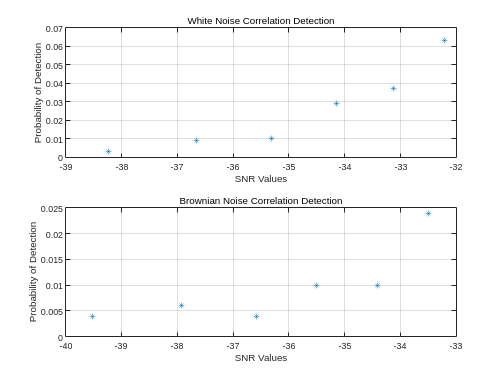

% --Plotting out Detection Data and Saving them
    figure()
    subplot(2,1,1)
    plot(W_SNRs, W_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("White Noise Correlation Detection")

    subplot(2,1,2)
    plot(B_SNRs, B_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("Brownian Noise Correlation Detection")

## Save Data File

% --Saving Data
    cd("/home/samkramer/Desktop")
    save("Correlation_Sim_6.mat","B_SNRs","B_detection", "W_detection","W_SNRs")